clc
clear all

load("result/theta_throughput_vs_N.mat")
load("result/gamma_throughput_vs_N.mat")

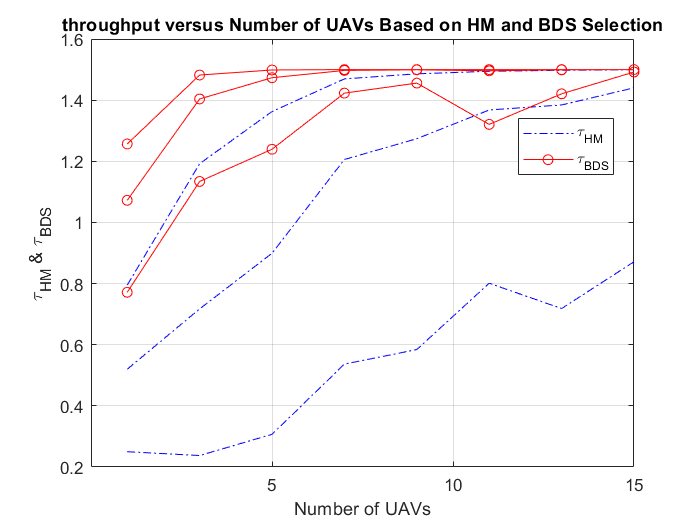

gamma_NF_db = [5:30];
gamma_NF = 10.^(gamma_NF_db/10);

figure
plot([1:2:15], gamma_throughput_vs_N, '-.b');
hold on
plot([1:2:15], theta_throughput_vs_N, '-or');

legend({'\tau_{HM}', '', '', '\tau_{BDS}'}, 'Location', 'best')


xlabel('Number of UAVs'); ylabel('\tau_{HM} & \tau_{BDS}');
title('throughput versus Number of UAVs Based on HM and BDS Selection')
grid on, hold on
% ylim([1e-4 1])
% xlim([1 15])
xticks(5:5:30)


% annotation('textarrow', [0.5,0.3], [0.4,0.7], 'String', 'N = 1,2,3,4', 'LineWidth', 0.1);